透射系数

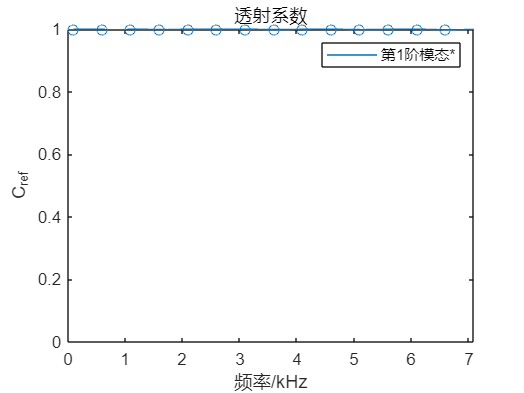

clear cti
kFactor = 2*pi*B/MATERIAL.CT; % 无量纲频率放大系数

fig(2)=figure;
legendText = [];
for ii = 1:nff
	tmp = cT{ii};
	nmode = length(tmp);
	for imode = 1:nmode
		ct(ii,imode) = tmp(imode);
	end
end

imode = mode_in;
idx = find(ct(:,imode));
iff = ff(idx);
ict = ct(idx,imode);
ffi = linspace(min(iff),max(iff),1000);
cti(:,imode) = interp1(iff,ict,ffi,'spline');

pic = plot(ffi*kFactor,cti(:,imode),'SeriesIndex',imode);
hold on
plot(iff*kFactor,ict(:),'o','SeriesIndex',imode)
legendText = [legendText;convertCharsToStrings(['第', num2str(imode), '阶模态*'])];


hold off


xlim([0 7e6*kFactor]);	ylim([0 1])
xlabel('频率/kHz')
ylabel('C_{ref}')
legend(pic,legendText)

title('透射系数')

反射系数

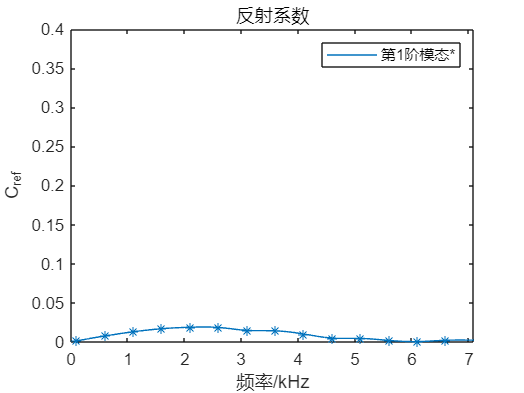

fig(1) = figure;
legendText = [];
for ii = 1:nff
	tmp = cR{ii};
	nmode = length(tmp);
	for imode = 1:nmode
		cr(ii,imode) = tmp(imode);
	end
end


imode = mode_in;
idx = find(cr(:,imode));
iff = ff(idx);
ict = cr(idx,imode);
ffi = linspace(min(iff),max(iff),1000);
cri(:,imode) = interp1(iff,ict,ffi,'spline');
pic = plot(ffi*kFactor,cri(:,imode),'SeriesIndex',imode);
hold on
plot(iff*kFactor,ict(:),'*','SeriesIndex',imode)
legendText = [legendText;convertCharsToStrings(['第', num2str(imode), '阶模态*'])];

hold off

xlim([0,7e6*kFactor]);	ylim([0 0.4])
xlabel('频率/kHz')
ylabel('C_{ref}')
legend(pic,legendText)
% legend('1阶透射系数','','2阶透射系数','','3阶透射系数','','Location','northeastoutside')
title('反射系数')


error("程序已完成，下面是保存/加载fig")

程序已完成，下面是保存/加载fig

保存fig

savefig(fig,['E:\MyProject\matlab\MATLAB Drive\DtN-FEM3\result\coefficients\' ...
	'm1.fig'])

读取fig

openfig(['E:\MyProject\matlab\MATLAB Drive\DtN-FEM3\result\coefficients\' ...
	'm1.fig'],'visible')
